# Demo for using the kbstat library

For more information, see the header of kbstat.m. For most options there is a default, so they do not all have to be provided. Here are the available options for chosing the distribution and link function.

fprintf('Initializing...\n');

Initializing...


## Clear workspace and close open figures

clear
close all

## Restore default path

restoredefaultpath;

## Add library and subfolders to path

addpath(genpath('../../kbstat')); % Location of kbstat library relative to current working directory

## Provide basic options

options = struct; % Init empty structure
options.inFile = 'iris_long.csv'; % Relative path to input file in long format (can be CSV or Excel)
options.outDir = 'Results'; % Relative path to output folder
options.closeFigures = 'false'; % Do not automatically close figures after saving them, so that they are showing in the live script
options.distribution = 'normal'; % Distribution family of GLM
options.link = 'identity'; % Link function of GLM
options.fitMethod = 'MPL'; % Fitting method of GLM
options.outlierMethod = 'quartiles'; % Remove outliers using this method 
options.postOutlierMethod = 'quartiles'; % Remove outliers after model fit using this method
options.showVarNames = 'Levels'; % Write levels with capitalized first letter

## Alternative 1: Explicitly define variable types

Define model variables and their roles explicitly

options.y = 'value'; % Dependent variable of model
options.yUnits = 'm'; % Units of dependent variable
options.x = 'species, attribute, measure'; % Fixed-effect variables
options.id = 'id'; % Random-effect variable

Call main script with the given options

Performing GLMM analysis for value...
	value ~ species*attribute*measure + (species+attribute+measure|id)
Fitting the model...done in 2.1361 seconds
Removing 15 post-fit outliers from 594 observations (2.5 %) using 'quartiles'...
Re-fitting model...Removed 6 pre-fit outlier(s) from 600 observations (1.0 %) using removal method 'quartiles'
Removed 15 post-fit outlier(s) from 594 observations (2.5 %) using removal method 'quartiles'


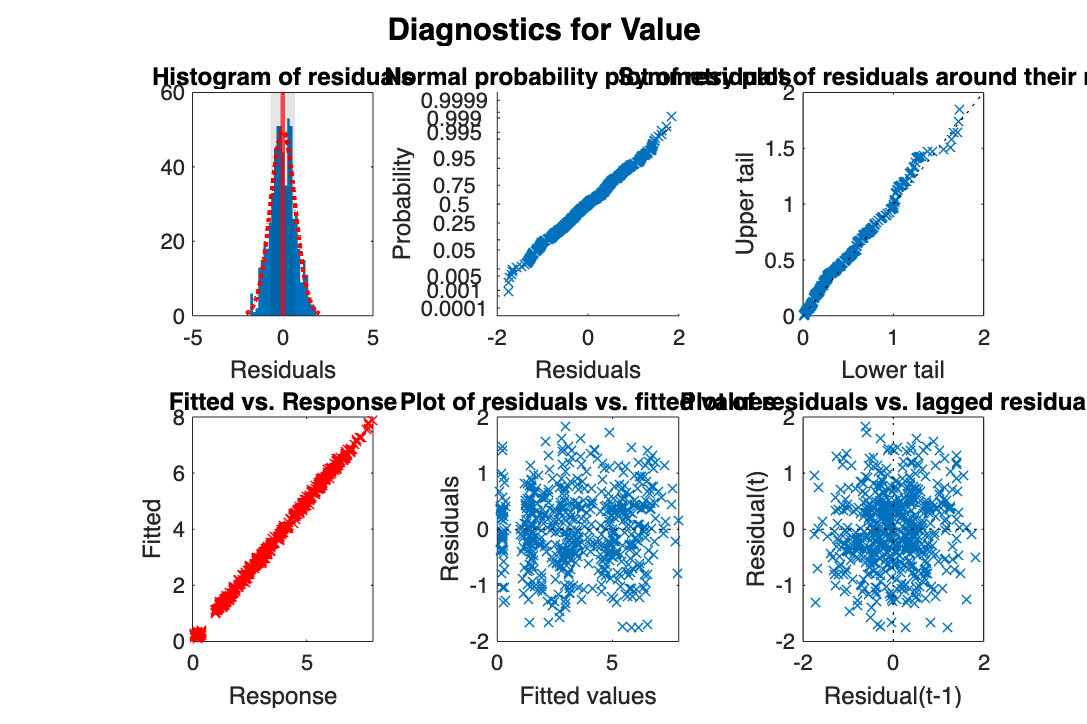

               Term                DF1    DF2      F           p          etaSqp        effectSize        significance
    ___________________________    ___    ___    ______    __________    ________    _________________    ____________

    "(Intercept)"                   1     567     22140             0     0.97503    "very large"            "***"    
    "species"                       2     567    648.29             0     0.69575    "very large"            "***"    
    "attribute"                     1     567    9227.7             0     0.94211    "very large"            "***"    
    "measure"                       1     567    8937.5             0     0.94034    "very large"            "***"    
    "species:

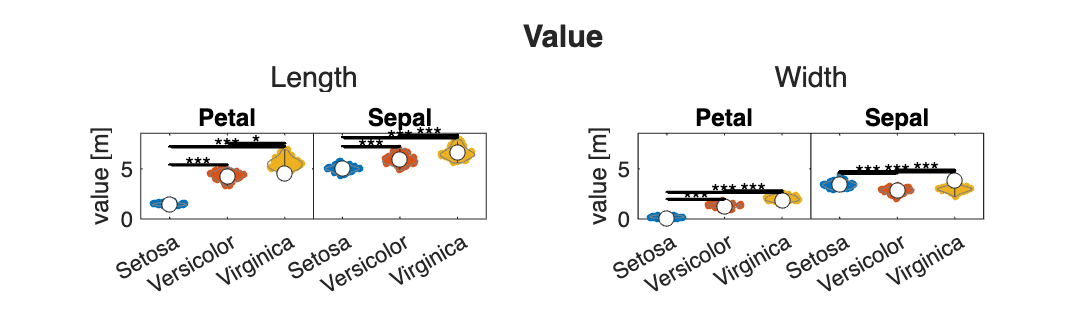

    measure     attribute     species_1       species_2            emmCI_1                emmCI_2               p           pCorr         diff      diffpct      F       DF1    DF2      SMD       etaSqp      effectSize     significance
    ________    _________    ____________    ____________    ___________________    ___________________    ___________    __________    ________    _______    ______    ___    ___    _______    ________    _______

kbstat(options);

## Alternative 2: Provide Wilkinson formula

The Wilkinson formula uniquely defines all variables and their role. If provided, it overrides any explicitly defined variables. The following Wilkinson formula produces the same results as Alternative 1.

options.formula = 'length ~ species*attribute*measure + (1|id)'; % Wilkinson formula of the model

Call main script with the given options

Performing GLMM analysis for value...
	value ~ species*attribute*measure + (1|id)
Fitting the model...done in 0.104963 seconds
Removing 15 post-fit outliers from 594 observations (2.5 %) using 'quartiles'...
Re-fitting model...Removed 6 pre-fit outlier(s) from 600 observations (1.0 %) using removal method 'quartiles'
Removed 15 post-fit outlier(s) from 594 observations (2.5 %) using removal method 'quartiles'


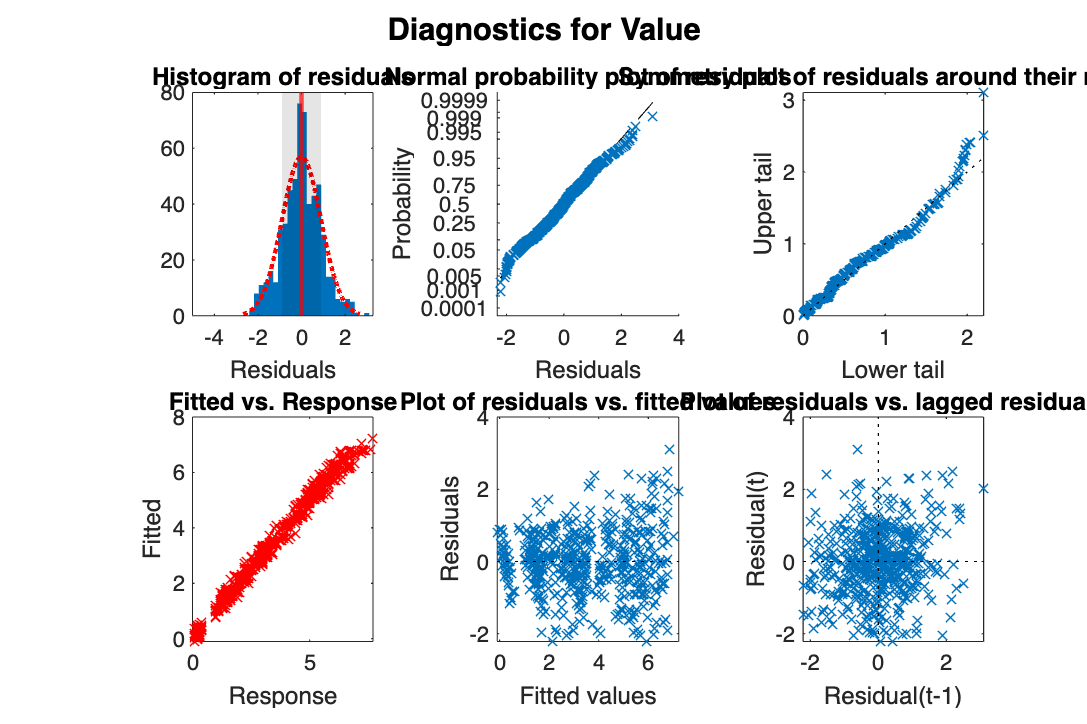

               Term                DF1    DF2      F           p          etaSqp         effectSize        significance
    ___________________________    ___    ___    ______    __________    _________    _________________    ____________

    "(Intercept)"                   1     567     24035             0      0.97695    "very large"            "***"    
    "species"                       2     567    506.98             0      0.64136    "very large"            "***"    
    "attribute"                     1     567    9442.7             0      0.94335    "very large"            "***"    
    "measure"                       1     567     16861             0      0.96747    "very large"            "***"    
    "sp

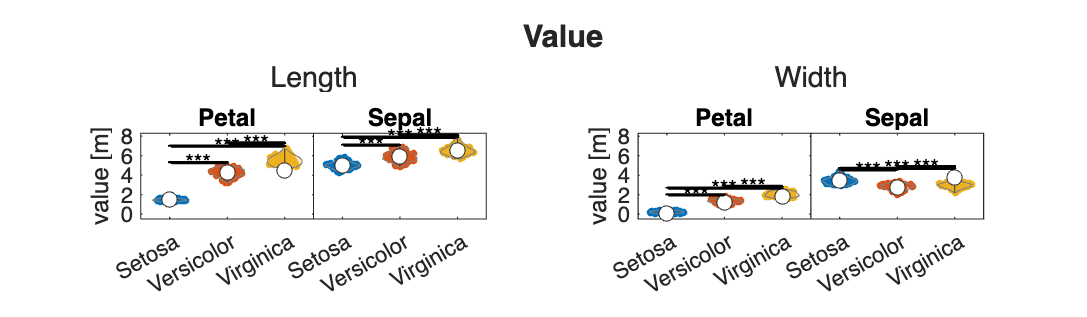

    measure     attribute     species_1       species_2            emmCI_1                 emmCI_2               p           pCorr         diff      diffpct      F       DF1    DF2      SMD       etaSqp      effectSize     significance
    ________    _________    ____________    ____________    ____________________    ___________________    ___________    __________    ________    _______    ______    ___    ___    _______    ________    _____

kbstat(options);